A=[1 2 3 3;4 5 6 3;7 8 9 3]
A(2:end,:)
A(1,:)
size(A,2)
zeros(1,size(A,2))
r=[zeros(1,size(A,2));A]

r2=[A(:,:);zeros(1,size(A,2))]
A2=r-r2
 
m=mod(A2+256,256)

clear all; close all;
A=imread('bird.pgm');
subplot(1,2,1)
imshow(A);
histograma=histc(A(:),[0:255]);
H=entropiaMHC(histograma)

prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =     12
    13
    15
    16
    17
    19
    20
    22
    23
    24


y = 6.7744

H = 6.7744

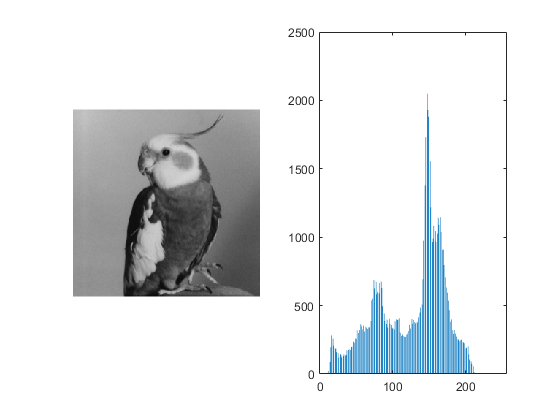

subplot(1,2,2); bar([0:255],histograma)


%Añadimos una fila de 0 al principio de la matriz
A1 = int16([zeros(1,size(A,2));A])

A1 = 257×256 int16 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   186   184   187   187   189   187   190   190   191   190   189   191   191   191   196   196   196   196   191   191   191   189   190   191   190   190   187   189   187   187   184   186   183   184   187   184   183   183   182   183   182   184   184   182   179   179   179   179   179   179
   183   184   186   186   189   187   190   190   190   189   187   191   193   190   194   194   194   194   190   193   191   187   189   190   190   190   187   189   186   186   184   183   184   186   186   184   183   183   184   183   180   183   184   183   180   183   180   180   179   177
   186   186   187   187   189   189   189   189   190   190   191   19

%Añadimos una fila de 0 al final de la matriz
A2 = int16([A(:,:);zeros(1,size(A,2))])

A2 = 257×256 int16 matrix
   186   184   187   187   189   187   190   190   191   190   189   191   191   191   196   196   196   196   191   191   191   189   190   191   190   190   187   189   187   187   184   186   183   184   187   184   183   183   182   183   182   184   184   182   179   179   179   179   179   179
   183   184   186   186   189   187   190   190   190   189   187   191   193   190   194   194   194   194   190   193   191   187   189   190   190   190   187   189   186   186   184   183   184   186   186   184   183   183   184   183   180   183   184   183   180   183   180   180   179   177
   186   186   187   187   189   189   189   189   190   190   191   191   190   193   193   193   193   193   193   190   191   191   190   190   189   189   189   189   187   187   186   186   187   187   183   183   184   186   184   184   182   182   184   180   179   180   180   180   179   177
   187   187   187   186   186   190   190   187   189   190   191   19


%Calculamos las diferencias y eliminamos la fila
%de ceros delfinal
Diferencias = int16(A1)-int16(circshift(A1,[0 -1]))

Diferencias = 257×256 int16 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    2   -3    0   -2    2   -3    0   -1    1    1   -2    0    0   -5    0    0    0    5    0    0    2   -1   -1    1    0    3   -2    2    0    3   -2    3   -1   -3    3    1    0    1   -1    1   -2    0    2    3    0    0    0    0    0   -1
   -1   -2    0   -3    2   -3    0    0    1    2   -4   -2    3   -4    0    0    0    4   -3    2    4   -2   -1    0    0    3   -2    3    0    2    1   -1   -2    0    2    1    0   -1    1    3   -3   -1    1    3   -3    3    0    1    2    0
    0   -1    0   -2    0    0    0   -1    0   -1    0    1   -3    0    0    0    0    0    3   -1    0    1    0    1    0    0    0    2    0    1    0   -1    0    4    0   -1   -2    2    0    2    0   -2  

Diferencias(end,:) = []

Diferencias = 256×256 int16 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    2   -3    0   -2    2   -3    0   -1    1    1   -2    0    0   -5    0    0    0    5    0    0    2   -1   -1    1    0    3   -2    2    0    3   -2    3   -1   -3    3    1    0    1   -1    1   -2    0    2    3    0    0    0    0    0   -1
   -1   -2    0   -3    2   -3    0    0    1    2   -4   -2    3   -4    0    0    0    4   -3    2    4   -2   -1    0    0    3   -2    3    0    2    1   -1   -2    0    2    1    0   -1    1    3   -3   -1    1    3   -3    3    0    1    2    0
    0   -1    0   -2    0    0    0   -1    0   -1    0    1   -3    0    0    0    0    0    3   -1    0    1    0    1    0    0    0    2    0    1    0   -1    0    4    0   -1   -2    2    0    2    0   -2  

histogramaDife = histc(Diferencias(:),[-255:255]);
HDife = entropiaMHC(histogramaDife)

prod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k =    159
   166
   168
   169
   176
   178
   181
   182
   183
   184


y = 4.2189

HDife = 4.2189


%Calculamos la el modulo 256 de las diferencias
modulo = mod(Diferencias+256,256)

modulo = 256×256 int16 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2   253     0   254     2   253     0   255     1     1   254     0     0   251     0     0     0     5     0     0     2   255   255     1     0     3   254     2     0     3   254     3   255   253     3     1     0     1   255     1   254     0     2     3     0     0     0     0     0   255
   255   254     0   253     2   253     0     0     1     2   252   254     3   252     0     0     0     4   253     2     4   254   255     0     0     3   254     3     0     2     1   255   254     0     2     1     0   255     1     3   253   255     1     3   253     3     0     1     2     0
     0   255     0   254     0     0     0   255     0   255     0 

histogramaMod256 = histc(modulo(:),[0:255]);
HMod256 = entropiaMHC(histogramaMod256)

prod =     0.2137
    0.1003
    0.0873
    0.0790
    0.0356
    0.0172
    0.0120
    0.0115
    0.0044
    0.0041


k =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


y = 4.2189

HMod256 = 4.2189


disp("Diferencias")

Diferencias


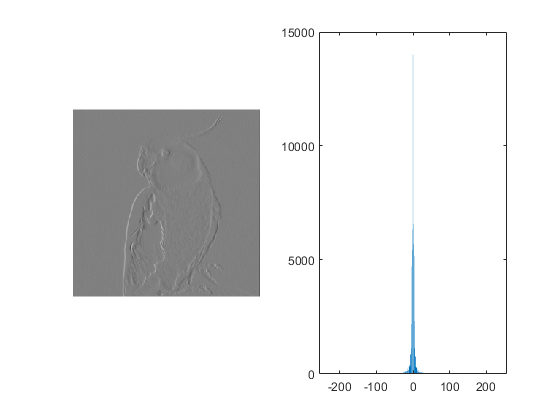

subplot(1,2,1,"replace");
imshow(Diferencias,[-255 255]);
subplot(1,2,2); 
bar([-255:255],histogramaDife)


disp("Diferencias mod 256")

Diferencias mod 256


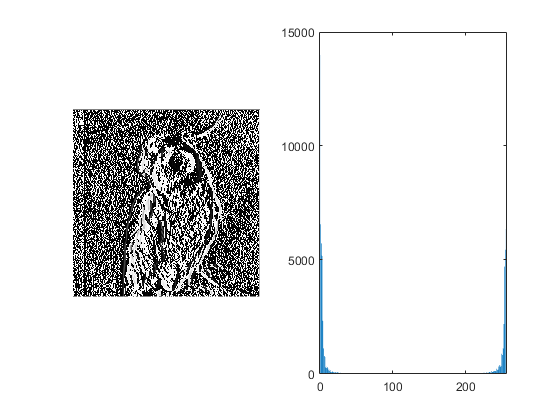

subplot(1,2,1,"replace")
imshow(modulo,[0 255]);
subplot(1,2,2)
bar([0:255],histogramaMod256)

clear all; close all;
A=imread('bird.pgm');

M = [1 2 3;4 5 6;7 8 9]

M =      1     2     3
     4     5     6
     7     8     9


circshift(M,[0 -1])

ans =      2     3     1
     5     6     4
     8     9     7
